## Benchmark of RAT Bayes Calculation

Start with a direct calculation of the posteriors for a simple problem. We use a simple reflectivity from D2O, and fit only two parameters - Roughness and background. 

The task is to calculate chi-squared on a 2D grid, with one axis representing roughness and the other background. For each pair of values, the likelihood is given by

 $P\propto \exp \left(-\frac{\chi^2 }{2}\right)$ . 

We calculate this on a grid, and this then gives the benchmark posterior distributions which can then be used to validate the two Bayes algorithms included in RAT.

1. **Calculation of 2D posterior.**

Start by setting up the problemDef and controlsDef input classes. We do this by converting from a RasCAL1 project.

problem = r1ToProjectClass('defaultProject.mat')

debug
debug


problem =          ModelType: 'standard layers'
    experimentName: 'defaultProject'
          Geometry: 'air/substrate'

    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min    Value     Max    Fit? 
    _    _____________________    ___    ______    ___    _____

    1    "Substrate Roughness"     3     4.8444     8     true 

    Layers: -------------------------------------------------------------------------------------------------- 

    Name    Thickness    SLD    Roughness    Hydration    Hydrate with
    ____    _________    ___  

Now we need to set up ranges for the parameters, and set up the calculation grid..

%Use a 30 x 30 grid.
%Make an array for the results...
gridSize = 30;
probArray = zeros(gridSize, gridSize);

% Make a vector of roughness values..
% Get the limits for roughness 
paramsTable = problem.parameters.paramsTable;
minRough = paramsTable{1,2};
maxRough = paramsTable{1,4};
roughVector = linspace(minRough, maxRough, gridSize);

%Also background...
backParsTable = problem.background.backPars.paramsTable;
minBack = backParsTable{1,2};
maxBack = backParsTable{1,4};
backsVector = linspace(minBack, maxBack, gridSize);

Now calculate the likelihood at all points on the grid

%Now for the calculation.
counter = 1;
totalGrid = gridSize^2;
controls = controlsDef();
controls.procedure = 'calculate';
controls.display = 'off';
tic;
for r = 1:gridSize
    for b = 1:gridSize
        thisRough = roughVector(r);
        thisBack =  backsVector(b);
        
        problem.setParameter(1,'value',thisRough);
        problem.setBacksPar(1,'value',thisBack);
        
        [outProblem,results] = RAT(problem,controls);
        thisChi = results.calculationResults.sum_chi;
        probArray(r,b) = exp(-thisChi/2);
        %percent = (counter/totalGrid)*100;
        %fprintf('Calculated %1.1f percent \n',percent);
        counter = counter + 1;
    end
end
toc;

Elapsed time is 0.006863 seconds.


We can now plot this to see the resulting 2D posterior....

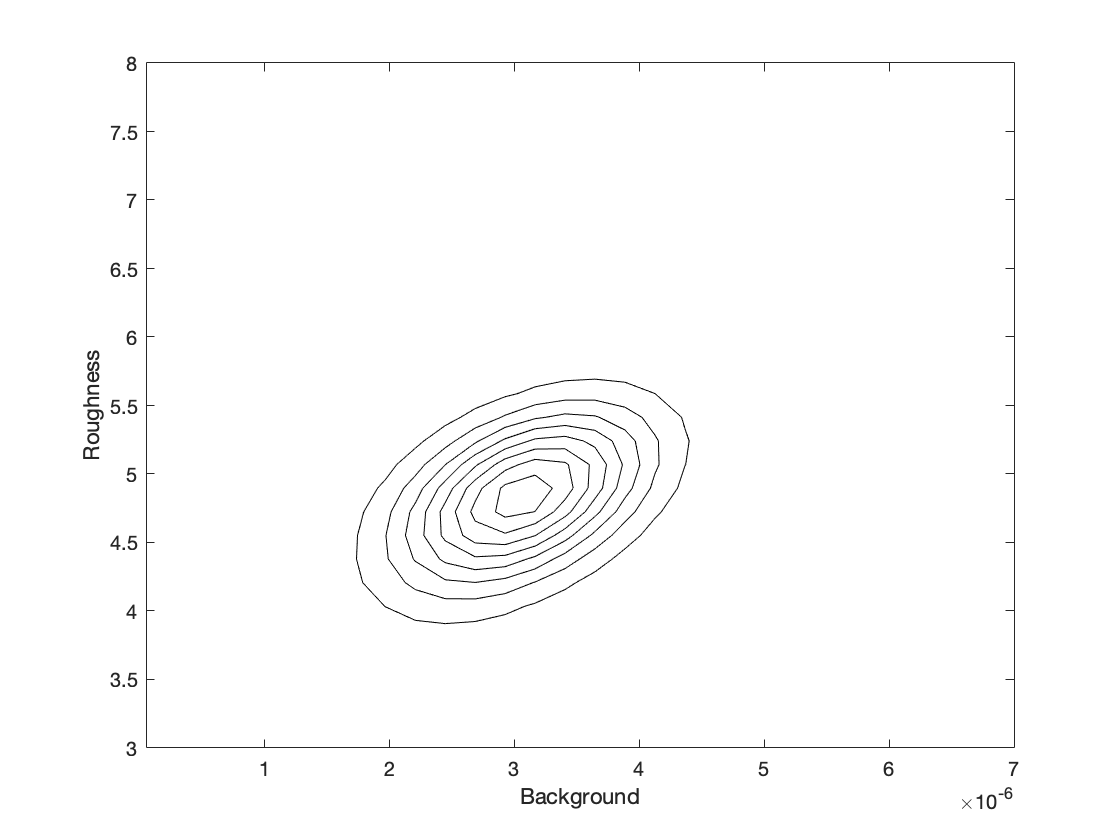

figure
contour(backsVector,roughVector,probArray,'k-');
hold on
xlabel('Background');
ylabel('Roughness')

We can now calculate the individual posterior distributions by margnalising along the other dimension. For roughness we sum over columns..

roughDist = sum(probArray,1);   % Sum over columns
backsDist = sum(probArray,2);   % Sum over rows

Normalise each distribution by simply dividing by the maximum value.

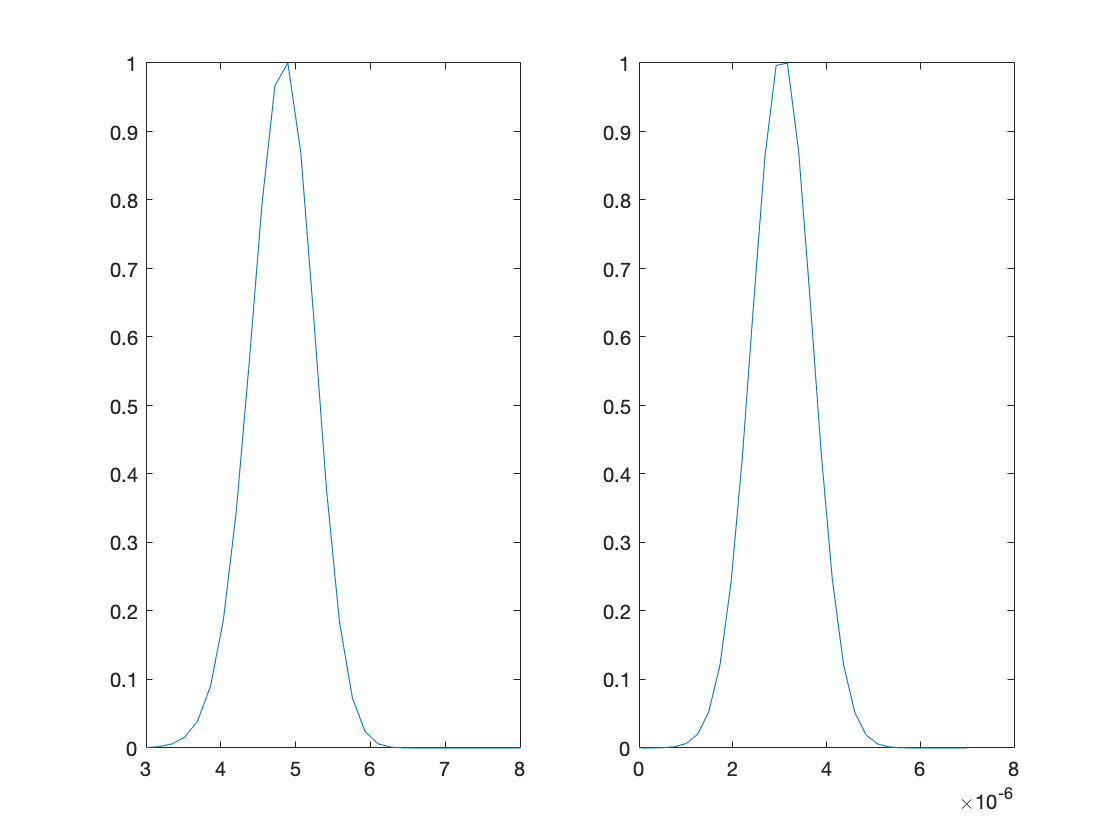

roughDist = roughDist ./ max(roughDist);
backsDist = backsDist ./ max(backsDist);

roughPosterior = [roughVector(:) backsDist(:)];
backsPosterior = [backsVector(:) roughDist(:)];

subplot(1,2,1);
plot(roughPosterior(:,1), roughPosterior(:,2));
subplot(1,2,2); 
plot(backsPosterior(:,1), backsPosterior(:,2));

### 2. Delayed Rejection Adaptive Metropolis.

Now run the analysis using DRAM, and compare the resulting posteriors to the calculated ones.

problem.setScalefactor(1,'fit',false);

controls.procedure = 'bayes';
controls.nsimu = 6000;
controls.repeats = 3;
tic;
[outProb,results] = RAT(problem,controls);

Running loop 1 of 3 
 Bayes:   3.3% [*·······································]
 Bayes: 100.0% [****************************************]

Running loop 2 of 3 Using values from the previous run

 Bayes: 100.0% [****************************************]

Running loop 3 of 3 Using values from the previous run

 Bayes: 100.0% [****************************************]




toc

Elapsed time is 19.753381 seconds.


We can get the posteriors from results.chain...

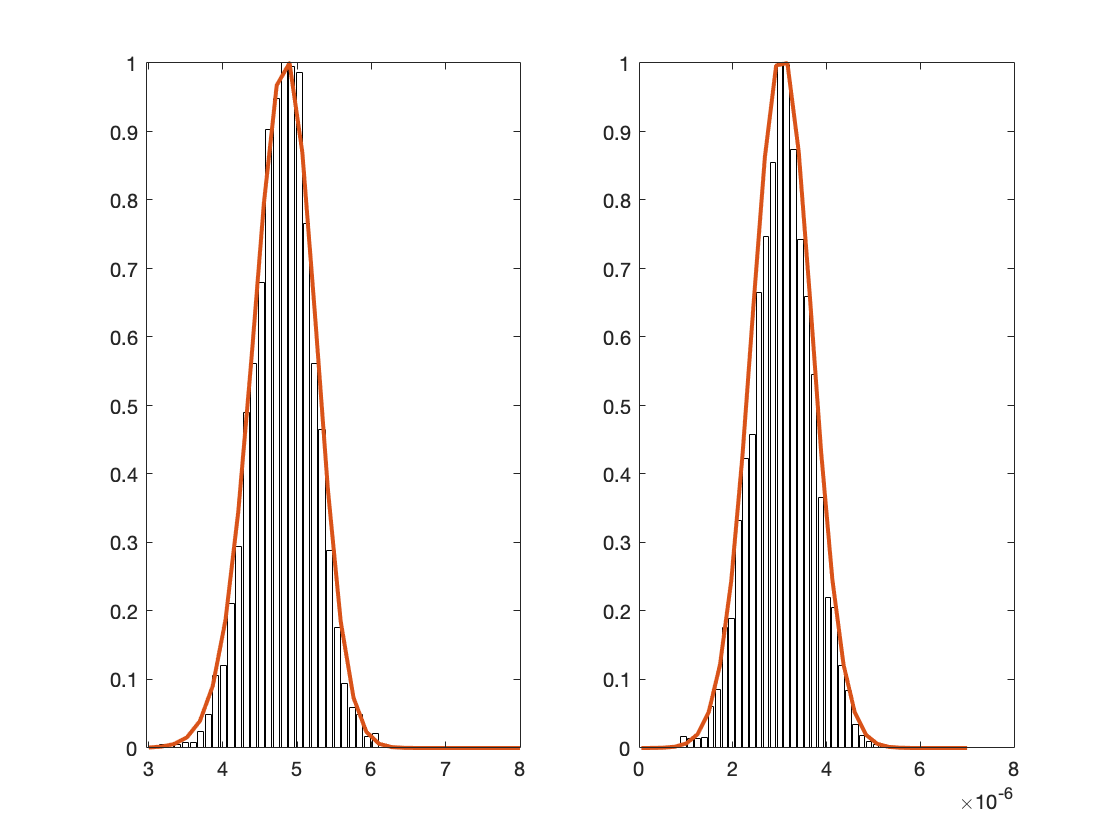

roughPostDram = results.chain(:,1);
backPostDram = results.chain(:,2);

[roughCounts,roughBins] = hist(roughPostDram,30);
roughCounts = roughCounts ./ max(roughCounts);

[backCounts,backBins] = hist(backPostDram,30);
backCounts = backCounts ./ max(backCounts);

subplot(1,2,1); bar(roughBins,roughCounts,'w');
hold on; plot(roughPosterior(:,1), roughPosterior(:,2), 'LineWidth', 2.0)
subplot(1,2,2); bar(backBins,backCounts,'w');
hold on; plot(backsPosterior(:,1), backsPosterior(:,2), 'LineWidth',2.0);

## 3. Nested Sampling

Nested sampling is primarily for model selection, but can be used to obtain the posteriors also. We do the same comparison as for DRAM.

In order to switch to NS, we just need to change the relevant flag in controlsDef...

controls.procedure = 'NS';
controls.Nlive = 200

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'NS'
    calcSldDuringFit: 'no'
             display: 'off'
               Nlive: 200
               Nmcmc: 0
           propScale: 0.1000
         nsTolerance: 1
           resamPars: [0.9000 50]


.. and run RAT..

tic;
[outNS,results] = RAT(problem,controls)

log(Z): -7.32952e+01, tol = 7.15315e+01, K = 1, iteration = 1, H = NaN
log(Z): -7.16487e+01, tol = 6.98800e+01, K = 1, iteration = 2, H = 3.793104e+00
log(Z): -7.10045e+01, tol = 6.92309e+01, K = 1, iteration = 3, H = 3.821986e+00
log(Z): -5.96366e+01, tol = 5.78579e+01, K = 1, iteration = 4, H = 5.315656e+00
log(Z): -5.63376e+01, tol = 5.45539e+01, K = 1, iteration = 5, H = 5.162595e+00
log(Z): -5.51698e+01, tol = 5.33811e+01, K = 1, iteration = 6, H = 4.655114e+00
log(Z): -5.44892e+01, tol = 5.26955e+01, K = 1, iteration = 7, H = 4.295630e+00
log(Z): -5.38098e+01, tol = 5.20111e+01, K = 1, iteration = 8, H = 4.115467e+00
log(Z): -5.30333e+01, tol = 5.12297e+01, K = 1, iteration = 9, H = 4.087177e+00
log(Z): -5.18835e+01, tol = 5.00749e+01, K = 1, iteration = 10, H = 4.322844e+00
log(Z): -5.06136e+01, tol = 4.87999e+01, K = 1, iteration = 11, H = 4.468375e+00
log(Z): -4.41802e+01, tol = 4.23616e+01, K = 1, iteration = 12, H = 5.342446e+00
log(Z): -4.29711e+01, tol = 4.11475e+01, K = 1

Output argument "results" (and maybe others) not assigned during call to "RAT_main".

Error in RAT (line 74)
[outProblemStruct,problem,result,bayesResults] = RAT_main(problemDef,problemDef_cells,problemDef_limits,priors,controls);

toc
posteriors = results.post_samples;
roughPostNS = posteriors(:,1);
backPostNS = posteriors(:,2);

[roughCountsNS,roughBinsNS] = hist(roughPostNS,20);
roughCountsNS = roughCountsNS ./ max(roughCountsNS);

[backCountsNS,backBinsNS] = hist(backPostNS,20);
backCountsNS = backCountsNS ./ max(backCountsNS);

subplot(1,2,1); bar(roughBinsNS,roughCountsNS,'w');
hold on; plot(roughPosterior(:,1), roughPosterior(:,2),'r-', 'LineWidth', 2.0)
subplot(1,2,2); bar(backBinsNS,backCountsNS,'w');
hold on; plot(backsPosterior(:,1), backsPosterior(:,2),'r-', 'LineWidth',2.0);

## 3. Overall Comparison

figure

hold on; box on

plot(backPostDram,roughPostDram,'r.')
contour(backsVector,roughVector,probArray,'k-','LineWidth',2);
plot(backPostNS,roughPostNS,'b.')